# Chapter 6, Section 1 (Part 1)

The goal of this activity is to spend some time reviewing the dot product of two vectors and some important properties. 

Let start with a definition. *Note that your instructor is now typing *$\textbf u$ *instead of *$\vec u$.

**Definition:** The dot product of two vectors $\textbf u$ and $\textbf{v}$ in $\mathbb R^n$ is defined as


$$\textbf u\cdot\textbf v=\textbf u^T\textbf v$$


We've been using the dot product to perform matrix multiplication, so some might find this definition a bit puzzling. To explain that it is the same as what we have been doing, let


$$\textbf u=\pmatrix{u_1\cr u_2\cr \vdots\cr u_n}\qquad\text{and}\qquad \textbf{v}=\pmatrix{v_1\cr v_2\cr \vdots\cr v_n}$$


Now, let's take the dot product. Note that we take the transpose of $\textbf u$.


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&\textbf u^T\textbf{v}\\
&=&\pmatrix{u_1\cr u_2\cr \vdots\cr u_n}^T\pmatrix{v_1\cr v_2\cr \vdots\cr v_n}\\
&=&\pmatrix{u_1 & u_2 & \cdots & u_n}\pmatrix{v_1\cr v_2\cr \vdots\cr v_n}\\
&=&u_1v_1+u_2v_2+\cdots+u_nv_n

\end{array}$$


Yes, it is precisely the same dot product definition we've been using to multiply a row of a matrix times a column of a matrix. 

# Example #1

Find the dot product of the vectors


$$\textbf u=\pmatrix{1\cr 2\cr 3}\qquad\text{and}\qquad\textbf v=\pmatrix{1\cr 2\cr 1}$$


**Solution:** Using the definition $\textbf u\cdot\textbf v=\textbf u^T\textbf v$, we can write:


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&\textbf u^T\textbf v\\
&=&\pmatrix{1 & 2 & 3}\pmatrix{1\cr 2\cr 1}\\
&=&(1)(1)+(2)(2)+(3)(1)\\
&=&1+4+3\\
&=&8
\end{array}$$


Note that there are a lot of skippable steps here. Most find it comfortable to do many calculations in their head and directly write


$$\begin{array}{rcl}
\textbf u\cdot \textbf v&=&(1)(1)+(2)(2)+(3)(1)\\
&=&8
\end{array}$$


Some might even say "Why bother with the definition $\textbf u\cdot\textbf v=\textbf u^T\textbf v$?" Well, we'll see in a moment. Now, we can also check our answer with Matalb.

u=[1;2;3];
v=[1;2;1];
dot(u,v)

ans = 8

Same answer. 

# Properties of the Dot Product

Here are some important properties of the dot product. Let $\textbf u$, $\textbf v$, and $\textbf w$ be vectors in $\mathbb R^n$ and let $c$ be a scalar in $\mathbb R$. Then,

- 
$$\textbf u\cdot \textbf u\ge \textbf{0}$$


- $\textbf u\cdot\textbf u=0$ if and only if $\textbf u=\textbf 0$

- 
$$\textbf u\cdot\textbf v=\textbf v\cdot\textbf u$$


- $\textbf u\cdot (\textbf v+\textbf w)=\textbf u\cdot\textbf v+\textbf u\cdot\textbf w$ and $(\textbf u+\textbf v)\cdot\textbf w=\textbf u\cdot\textbf w+\textbf v\cdot\textbf w$

- 
$$(c\textbf u)\cdot\textbf v=c(\textbf u\cdot\textbf v)=\textbf u\cdot(c\textbf v)$$


If $\textbf u=(c_1,c_2,\ldots,c_n)^T$, then 


$$\textbf u\cdot\textbf u=c_1^2+c_2^2+\cdots+c_n^2$$


so it is clear that $\textbf u\cdot\textbf u\ge 0$. Moreover, it is also clear that if $(c_1,c_2,\ldots,c_n)^T=(0,0,\ldots,0)^T$, then each of the $c$ values are zero, which means that $\textbf u\cdot\textbf u=0$. Similarly, if $\textbf u\cdot\textbf u=0$, that means that $c_1^2+c_2^2+\cdots+c_n^2=0$, which means each of the $c$-values must equal zero, which means that $\textbf u=\textbf 0$.

Let's use Matlab to verify properties 3, 4, and 5 for an example.

u=[1;2;5];
v=[-1;2;-1];
w=[4;5;2];
c=-2;

Now, how about property #3?

dot(u,v)

ans = -2

dot(v,u)

ans = -2

Both the same, so property #3 works. How about property #4?

dot(u,v+w)

ans = 22

dot(u,v)+dot(u,w)

ans = 22

Both the same, so property #4 works. How about property #5?

dot(c*u,v)

ans = 4

c*dot(u,v)

ans = 4

dot(u,c*v)

ans = 4

All three the same, so property #5 works.

# The Length of a Vector

Consider the following image. Note that we are taking the absolute value of each coordinate of $(u,v)$, as they might be negative. In this image, $u$ is negative and $v$ is positive, but we could be in any quadrant.

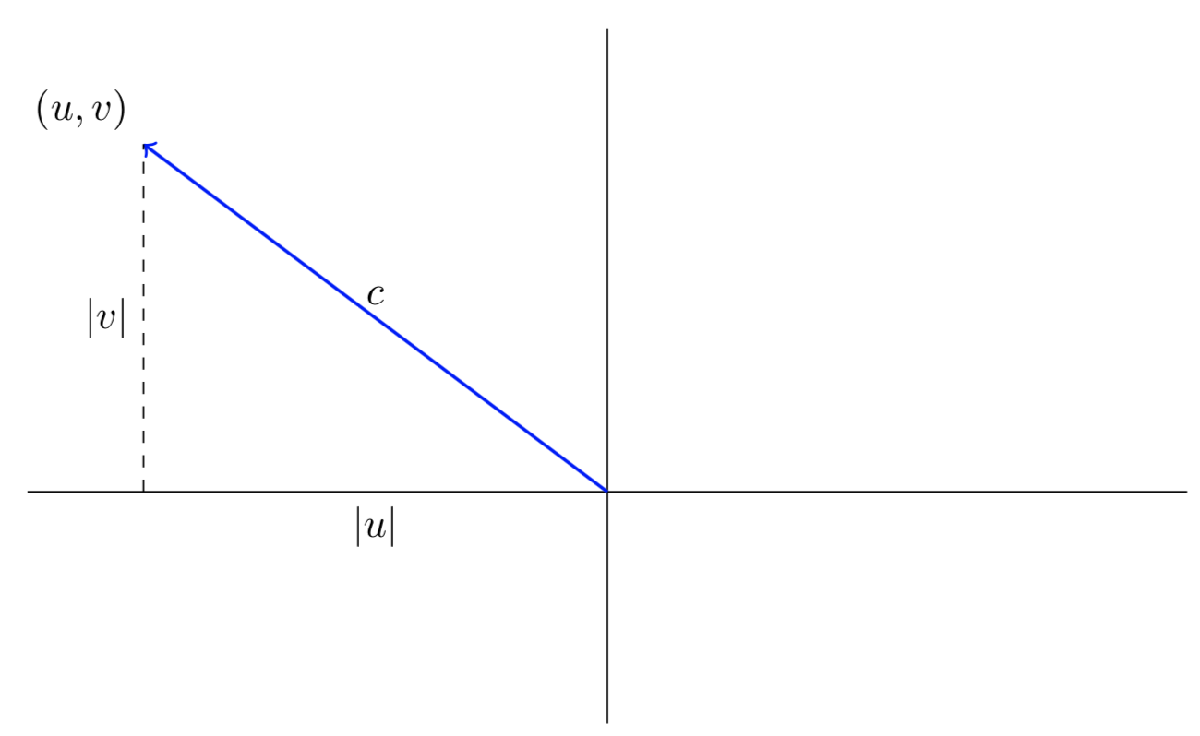

By the Pythagorean Theorem, the length $c$ of the vector $(u,v)^T$ is:


$$\begin{array}{rcl}
c^2&=&|u|^2+|v|^2\\
c^2&=&u^2+v^2
\end{array}$$


Now we can take the square root.


$$c=\sqrt{u^2+v^2}$$


It turns out that a similar technique can be used to find the length of a vector in $\mathbb R^n$.

**Definition:** Let $\textbf u=(u_1,u_2,\ldots,u_n)^T\in \mathbb R^n$. The length (also called the **norm**) of $\textbf u$ is calculated with:


$$||\textbf u||=\sqrt{u_1^2+u_2^2+\cdots+u_n^2}$$


In linear algebra, we use the symbolism $||\textbf u||$ to represent the length of a vector $\textbf u$.

# Example #2

Find the length (**norm**) of the vector $\textbf u=(3,4)^T$.

**Solution:** Let's draw an image.

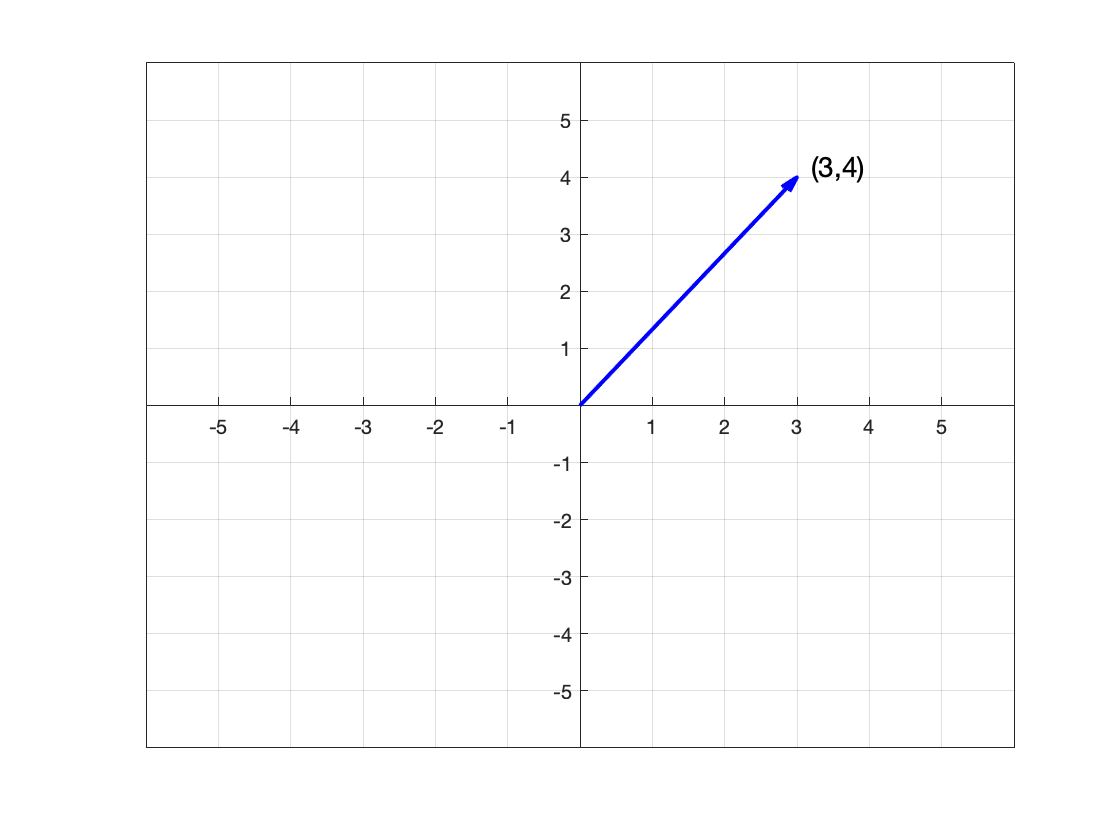

figure
u=[3;4];
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
grid on
axis([-6,6,-6,6])
xticks(-6:6)
yticks(-6:6)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(3.2,4.2,'(3,4)','FontSize',14)

Does it look like it is about 5 units long? Let's add a circle to our image with a radius of 5. Before we do this, let's add an image reminder of an important trigonometry defintion.

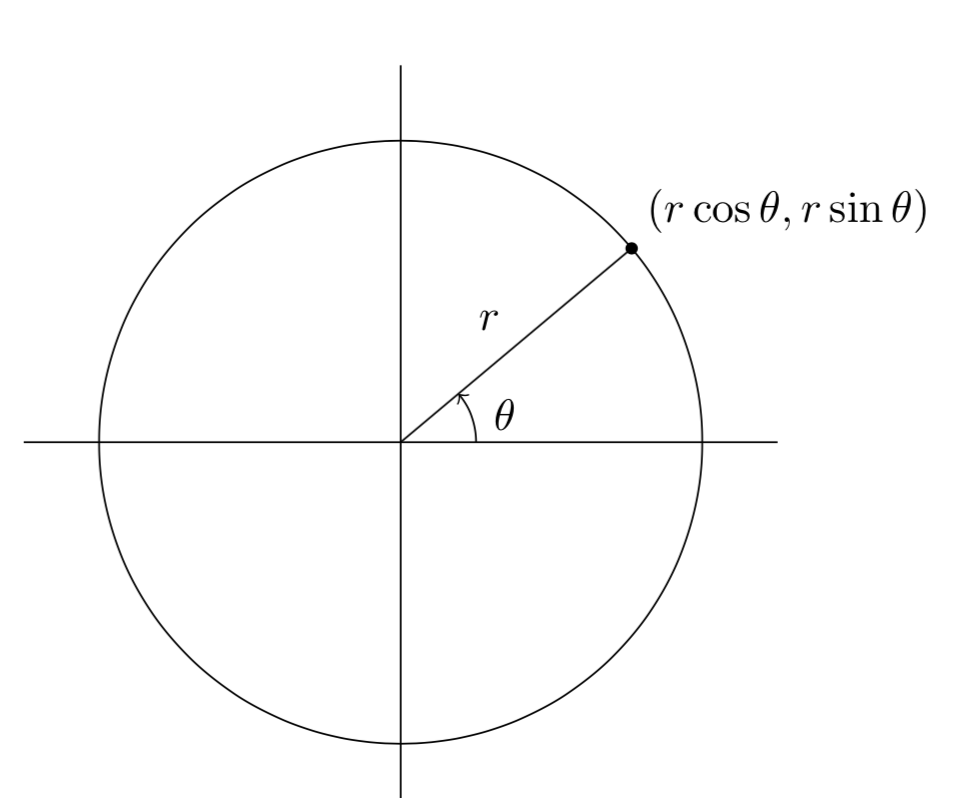

Now, we want a circle of radius $r=5$.

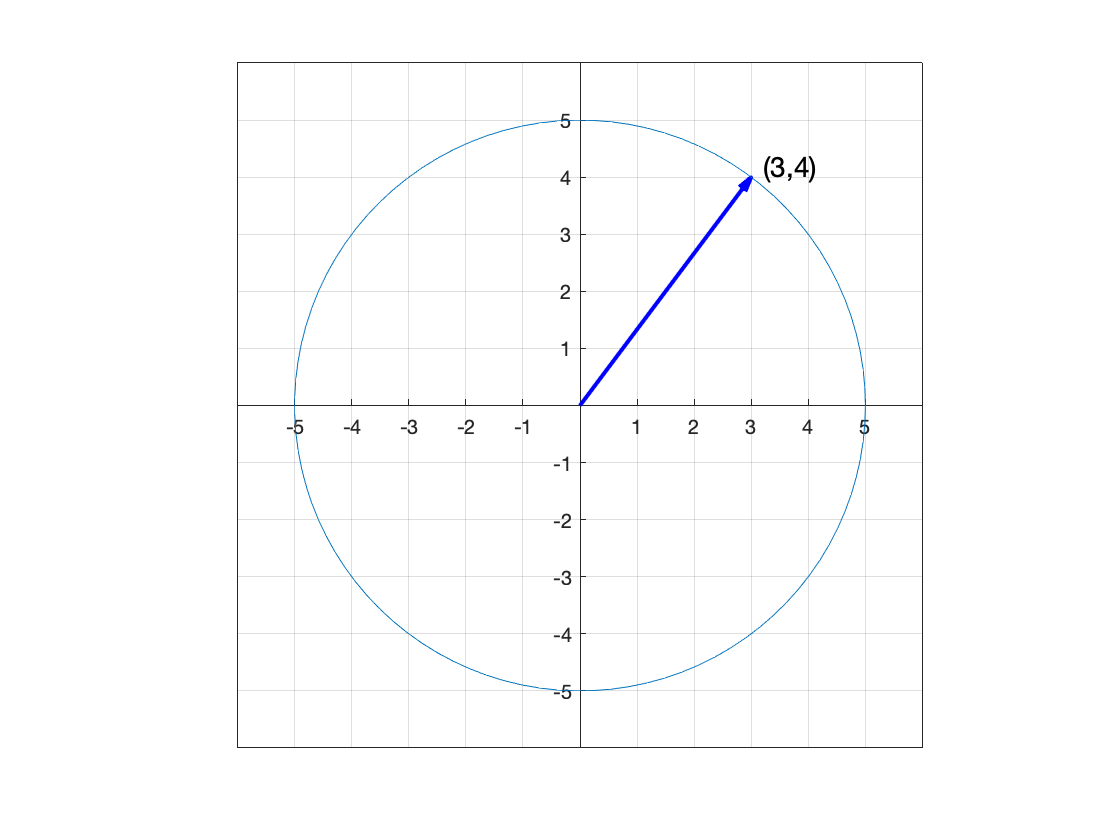

figure
u=[3;4];
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
hold on
t=linspace(0,2*pi);
x=5*cos(t);
y=5*sin(t);
plot(x,y)
grid on
axis equal
axis([-6,6,-6,6])
xticks(-6:6)
yticks(-6:6)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(3.2,4.2,'(3,4)','FontSize',14)

Indeed, our vector appears to have a length $r=5$. Now, let's use our definition to calculate the length (**norm**) of the vector $\textbf u=(3,4)^T$.


$$\begin{array}{rcl}
||\textbf{u}||&=&\sqrt{3^2+4^2}\\
&=&\sqrt{9+16}\\
&=&\sqrt{25}\\
&=&5
\end{array}$$


And we can check this with Matlab.

u=[3;4];
norm(u)

ans = 5

# Example #3

Find the length of the vector $\textbf u=(3,0,4)$.

**Solution:** Let's draw a sphere of radius 5, then add our vector to the image.

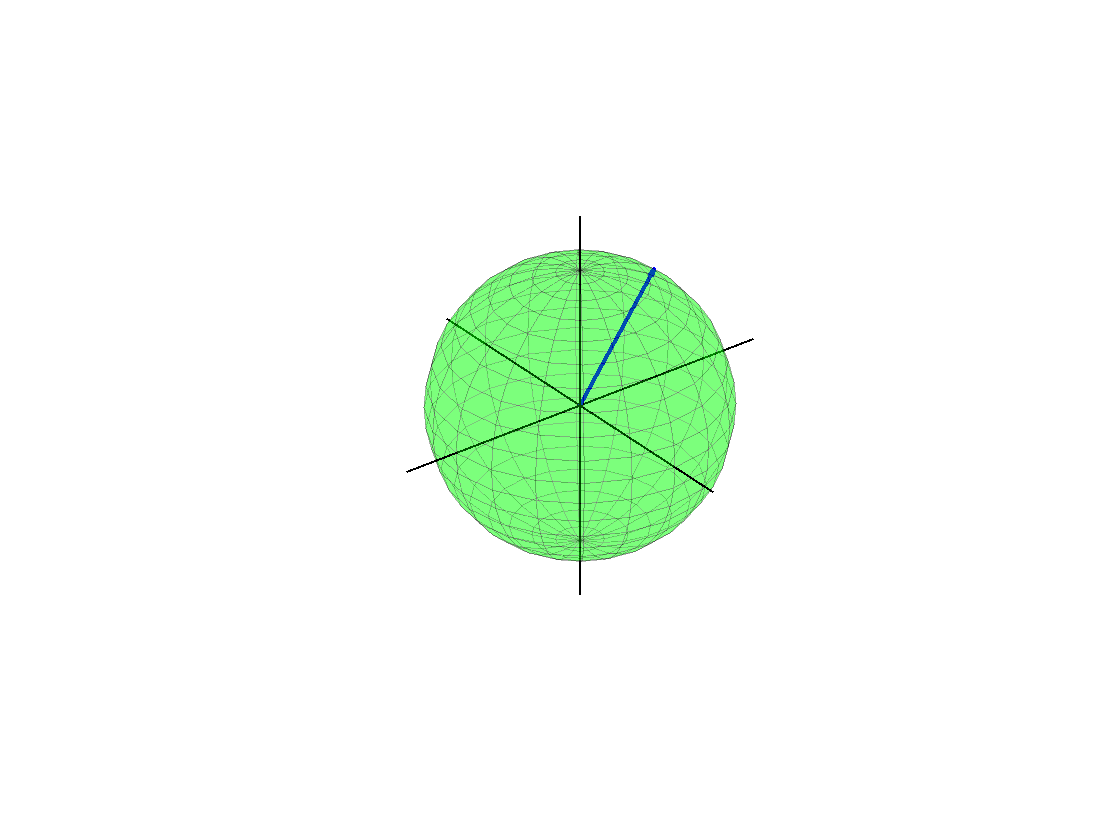

figure
u=[3;0;4];
[x,y,z]=sphere;
surf(5*x,5*y,5*z,'FaceColor','g','FaceAlpha',0.3,'EdgeAlpha',0.3)
hold on
line([-7,7],[0,0],[0,0],'LineWidth',1,'Color','k')
line([0,0],[-7,7],[0,0],'LineWidth',1,'Color','k')
line([0,0],[0,0],[-7,7],'LineWidth',1,'Color','k')
quiver3(0,0,0,u(1),u(2),u(3),0,'LineWidth',2,'Color','b')
axis equal
set(gca,'visible','off')

It appears that the vector has length 5 since it starts at the center of the sphere and its tip touches the surface of the sphere of radius 5. Now, let's use our defintion to calculate the length of $\textbf u=(3,0,4)^T$.


$$\begin{array}{rcl}
||\textbf u||&=&\sqrt{3^2+0^2+4^2}\\
&=&\sqrt{9+0+16}\\
&=&\sqrt{25}\\
&=&5
\end{array}$$


Yes, it has length 5. And we can check this with Matlab.

u=[3;0;4];
norm(u)

ans = 5

Same answer. 

# Important Length Properties

We'll find these properties extremely useful.

# Example #4

Prove that $||\textbf u||^2=\textbf u\cdot\textbf u$ for any vector $\textbf u\in \mathbb R^n$.

**Proof: **Let $\textbf u=\pmatrix{u_1 & u_2 & \cdots & u_n}^T\in \mathbb R^n$. Then we can write


$$\begin{array}{rcl}
||\textbf u||&=&\sqrt{u_1^2+u_2^2+\cdots+u_n^2\\
||\textbf u||^2&=&u_1^2+u_2^2+\cdots+u_n^2
\end{array}$$


But


$$\begin{array}{rcl}
\textbf u\cdot\textbf u&=&\pmatrix{u_1\cr u_2\cr \vdots\cr u_n}\cdot \pmatrix{u_1\cr u_2\cr \vdots\cr  u_n}\\
\textbf u\cdot\textbf u&=&u_1^2+u_2^2+\cdots+u_n^2
\end{array}$$


so we've shown that $||\textbf u||^2=\textbf u\cdot\textbf u$. We can check this with a Matlab example.

u=[1;3;-2];
norm(u)^2

ans = 14

dot(u,u)

ans = 14

Yes, they are the same.

In the following image, we have a red arrow representing the vector $\textbf u=(2,1)^T$, and two blue arrows, one representing $\textbf v=2\textbf u$ and the other representing $\textbf w=-2\textbf u$.

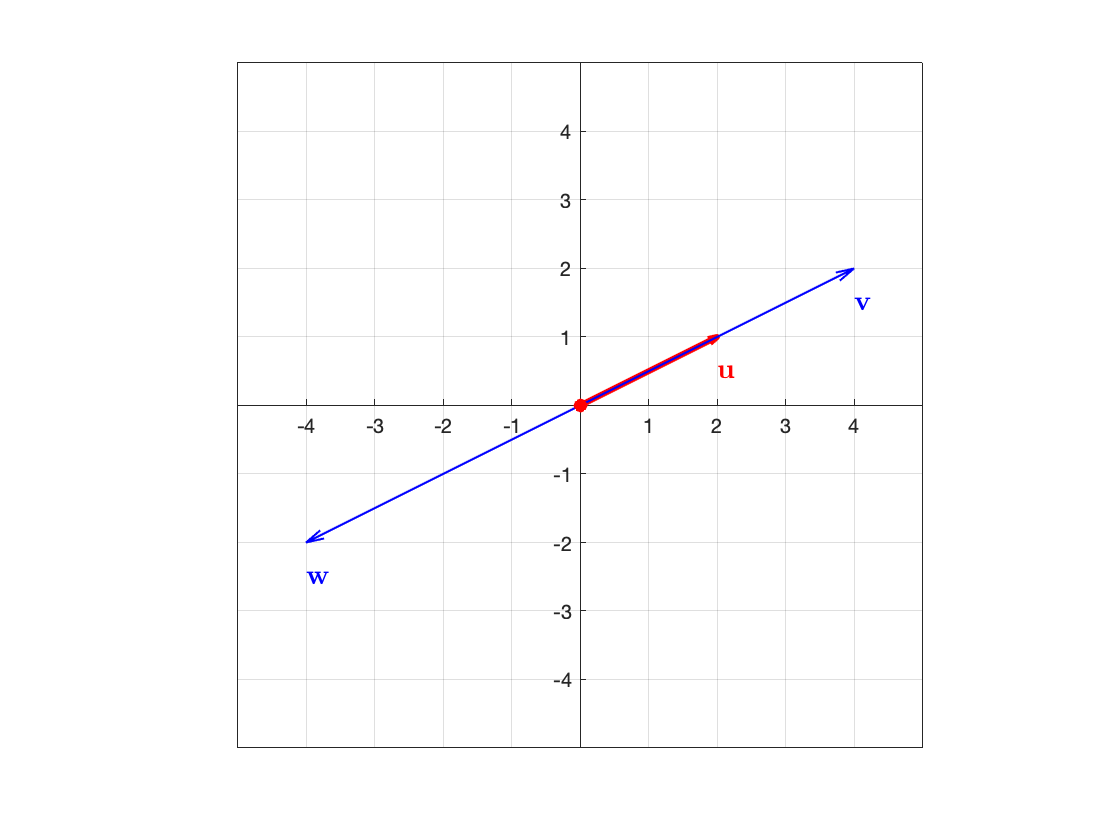

figure
u=[2;1];
v=2*u;
w=-2*u;
quiver(0,0,u(1),u(2),0,'LineWidth',3,'Color','r')
hold on
quiver(0,0,v(1),v(2),0,'LineWidth',1,'Color','b')
quiver(0,0,w(1),w(2),0,'LineWidth',1,'Color','b')
plot(0,0,'ro','MarkerFaceColor','r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2,0.5,'\textbf u','Color','r','FontSize',14,'Interpreter','latex')
text(4,1.5,'\textbf v','Color','b','FontSize',14,'Interpreter','latex')
text(-4,-2.5,'\textbf w','Color','b','FontSize',14,'Interpreter','latex')

Note that both $\textbf v$ and $\textbf w$ are twice the length of the vector $\textbf u$. Here are two important comments:

- Because $\textbf v=2\textbf u$, it is correct to state that $||\textbf v||=2||\textbf u||$.

- However, even though $\textbf w=-2\textbf u$, it is incorrect to say that $||\textbf w||=-2||\textbf u||$. This statement says the length of $\textbf w$ is negative, which is incorrect. The length of $\textbf w$ is positive.

# Example #5

Given that $\textbf u\in \mathbb R^n$ and $c\in \mathbb R$, show that $||c\textbf u||=|c|||\textbf u||$.

**Solution:** Before we begin the proof, it is very important that we know how to handle the symbolism $\sqrt{x^2}$. For example, the equation $x^2=25$ has two answers, $x=-5$ and $x=5$. The notation $-\sqrt{25}$ calls for the negative square root and the notation $\sqrt{25}$ calls for the non-negative square root. One of the most common mistakes we instructors make is to pronounce $\sqrt{x^2}$ as "the square root of $x$ squared," which is incorrect. The proper pronunciation is "the non-negative square root of $x$ squared."

When we pronounce $\sqrt{x^2}$ as the "square root of x squared", we seem to be meaning:


$$\sqrt{x^2}=x$$


Let's see if this is true for all real numbers $x$. Substitute $x=-2$.


$$\begin{array}{rcl}
\sqrt{(-2)^2}&=&-2\\
\sqrt{4}&=&-2\\
2&=&-2
\end{array}$$


See? That does not work. Now, let's pronounce $\sqrt{x^2}$ as "the non-negative square root of x squared," which forces us to do something to insure our answer is non-negative; that is, wrap our answer in absolute value bars.


$$\sqrt{x^2}=|x|$$


Now look what happens when we substitute $x=-2$.


$$\begin{array}{rcl}
\sqrt{(-2)^2}&=&|-2|\\
\sqrt{4}&=&2\\
2&=&2
\end{array}$$


It works! Important to Remember: If $x$ is any real number, then the "non-negative square root of $x$" is the absolute value of $x$. Now we can do the proof.

**Proof:** Note that $|c|$ means "absolute value of $c$," but $||\textbf u||$ means length (or **norm**) of $\textbf u$. Now we can use the properties we've shown above and write:


$$\begin{array}{rcl}
||c\textbf u||&=&\sqrt{(c\textbf u)\cdot(c\textbf u)\\
||c\textbf u||&=&\sqrt{c^2(\textbf u\cdot\textbf u)\\
||c\textbf u||&=&\sqrt{c^2}\sqrt{\textbf u\cdot\textbf u\\
||c\textbf u||&=&|c|||\textbf u||
\end{array}$$


# Example #6

Find a unit vector in the direction of $\textbf v=(2,2)^T$.

**Solution:** Let's share an image. The vector $\textbf v$ is colored in blue and we've draw a red vector $\textbf u$ in the direction of $\textbf v$ that has length 1.

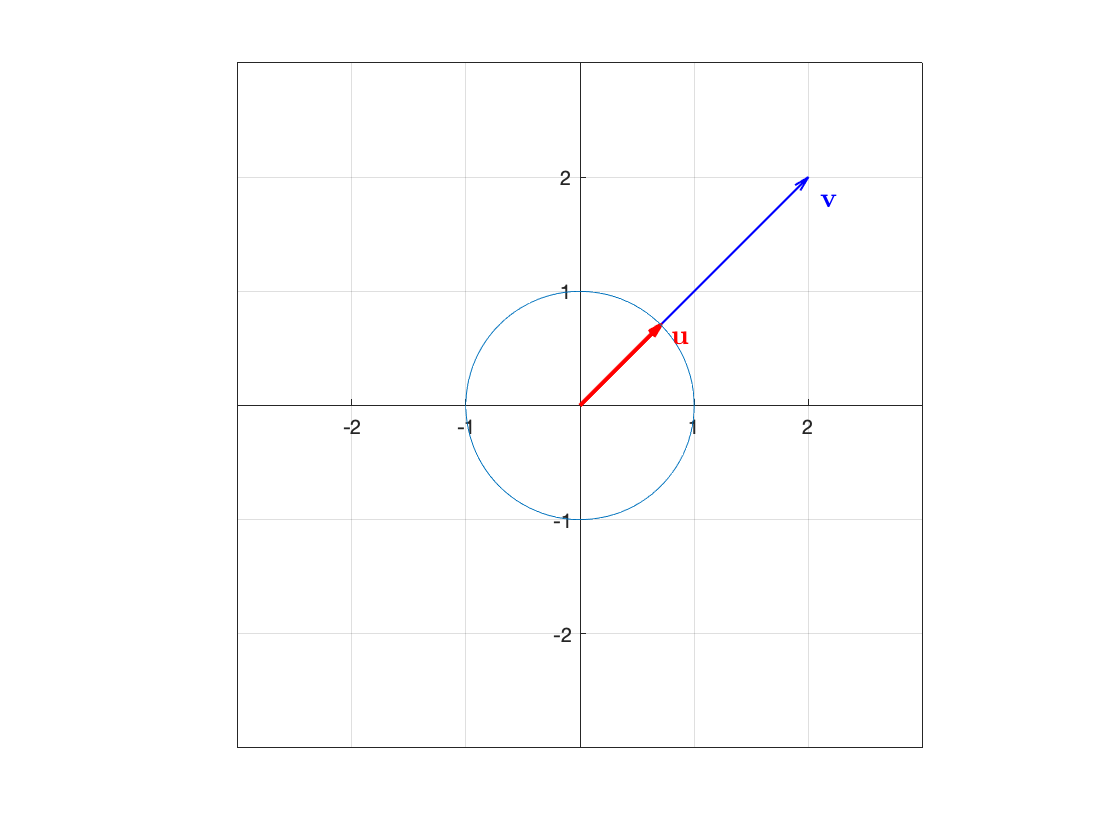

figure
v=[2;2];
u=v/norm(v);
quiver(0,0,v(1),v(2),0,'LineWidth',1,'Color','b')
hold on
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','r','MaxHeadSize',0.5)
t=linspace(0,2*pi);
x=cos(t); y=sin(t);
plot(x,y)
axis equal
axis([-3,3,-3,3])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(0.8,0.6,'\textbf u','FontSize',14,'Color','r','Interpreter','latex')
text(2.1,1.8,'\textbf v','FontSize',14,'Color','b','Interpreter','latex')

How did we figure out the coordinates of $\textbf u$? Our thought was "If we divide the vector $\textbf v$ by its length, then we'll have a vector of length one that points in the same direction as $\textbf v$. 


$$\begin{array}{rcl}
\textbf u&=&\frac{\textbf v}{||\textbf v||}\\
&=&\frac{1}{\sqrt{2^2+2^2}}\pmatrix{2\cr 2}\\
&=&\frac{1}{\sqrt 8}\pmatrix{2\cr 2}\\
&=&\frac{1}{2\sqrt2}\pmatrix{2\cr 2}\\
&=&\pmatrix{1/\sqrt2\cr 1/\sqrt2}
\end{array}$$


We can check this with Matlab.

v=[2;2];
u=v/norm(sym(v))

$$u = \left(\begin{array}{c} \frac{\sqrt{8}}{4}\\ \frac{\sqrt{8}}{4} \end{array}\right)$$

Is that the same as our answer? Let's try simplify.

u=simplify(u)

$$u = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

Note that


$$\begin{array}{rcl}
\frac{1}{\sqrt 2}&=&\frac{1}{\sqrt 2}\cdot \frac{\sqrt2}{\sqrt 2}\\
&=&\frac{\sqrt{2}}{2}
\end{array}$$


so this is the same as our answer.

# Distance Between Two Vectors

Let's recall from algebra how we computed the distance between two points in $\mathbb R^2$. Here is a reminder in an image.

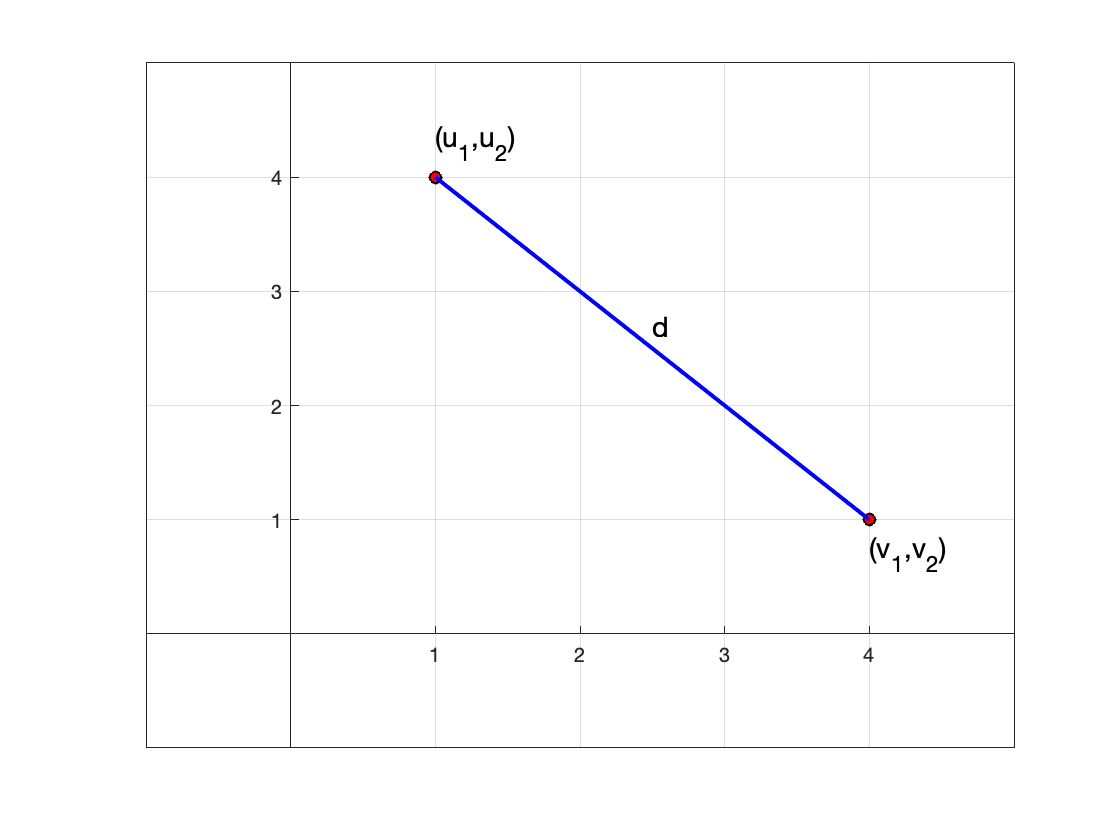

figure
plot(1,4,'ko','MarkerFaceColor','r')
hold on
plot(4,1,'ko','MarkerFaceColor','r')
line([1 4],[4,1],'LineWidth',2,'Color','b')
grid on
axis([-1,5,-1,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1,4.3,'(u_1,u_2)','FontSize',14)
text(4,0.7,'(v_1,v_2)','FontSize',14)
text(2.5,2.7,'d','FontSize',14)
hold off

Here is the Euclidean Distance Formula we used to calculate the distance between the two points.


$$d=\sqrt{(u_1-v_1)^2+(u_2-v_2)^2}$$


Now, how do we do this in linear algebra? Let's add some vectors to our image.

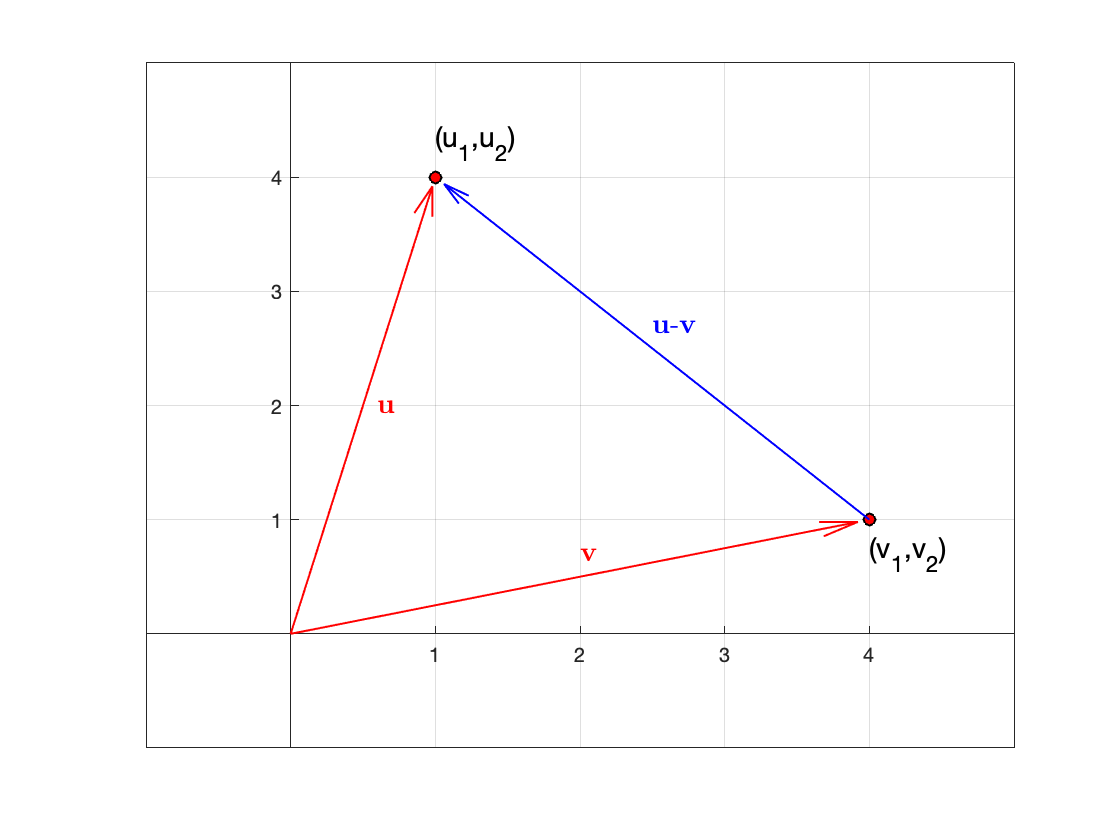

figure
plot(1,4,'ko','MarkerFaceColor','r')
hold on
plot(4,1,'ko','MarkerFaceColor','r')
quiver(0,0,4,1,0.98,'LineWidth',1,'Color','r')
quiver(0,0,1,4,0.98,'LineWidth',1,'Color','r')
quiver(4,1,-3,3,0.98,'LineWidth',1,'Color','b')
grid on
axis([-1,5,-1,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1,4.3,'(u_1,u_2)','FontSize',14)
text(4,0.7,'(v_1,v_2)','FontSize',14)
text(0.6,2,'\textbf u','FontSize',14,'Color','r','Interpreter','latex')
text(2.5,2.7,'\textbf u-\textbf v','FontSize',14,'Color','b','Interpreter','latex')
text(2,0.7,'\textbf v','FontSize',14,'Color','r','Interpreter','latex')
hold off

Now, the distance between the two points (or the tips of the two vectors) is equal to the length of the vector $\textbf u-\textbf v$.


$$\begin{array}{rcl}
d&=&||\textbf u-\textbf v||\\
d&=&\left|\left|\pmatrix{u_1\cr u_2}-\pmatrix{v_1\cr v_2}\right|\right|\\
d&=&\left|\left|\pmatrix{u_1-v_1\cr u_2-v_2}\right|\right|\\
d&=&\sqrt{(u_2-v_1)^2+(u_2-v_2)^2}
\end{array}$$


Wow! The same formula.

# Example #7

Find the distance between the two vectors $\textbf u=(-2,3)^T$ and $\textbf v=(3,1)^T$.

**Solution: **Let's draw an image.

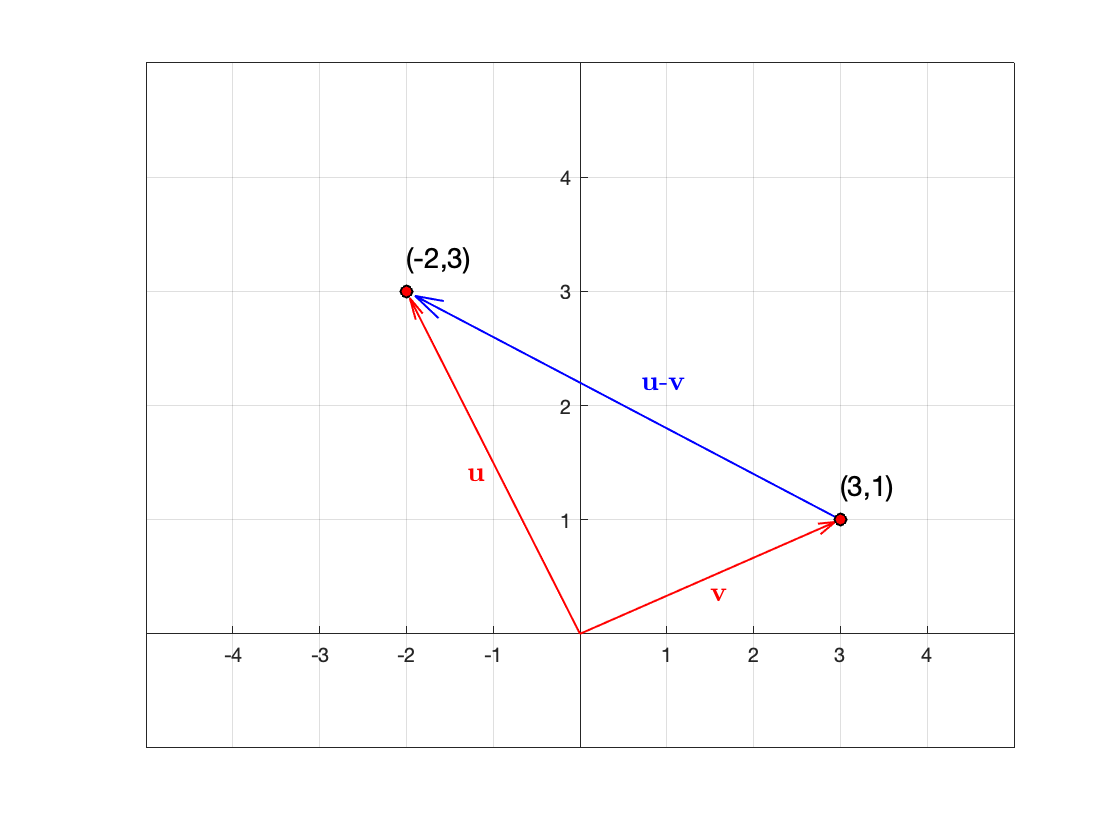

figure
quiver(0,0,-2,3,0.98,'LineWidth',1,'Color','r')
hold on
quiver(0,0,3,1,0.98,'LineWidth',1,'Color','r')
quiver(3,1,-5,2,0.98,'LineWidth',1,'Color','b')
plot(-2,3,'ko','MarkerFaceColor','r')
plot(3,1,'ko','MarkerFaceColor','r')
grid on
axis([-5,5,-1,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(3,1.3,'(3,1)','FontSize',14)
text(-2,3.3,'(-2,3)','FontSize',14)
text(-1.3,1.4,'\textbf u','Color','r','FontSize',14,'Interpreter','Latex')
text(1.5,0.35,'\textbf v','Color','r','FontSize',14,'Interpreter','Latex')
text(0.7,2.2,'\textbf u-\textbf v','Color','b','FontSize',14,'Interpreter','Latex')
hold off

Staring at the image, it seems the length of $\textbf u-\textbf v$ is a little longer than 5. Let's calculate the distance between the two vectors.


$$\begin{array}{rcl}
d&=&||\textbf u-\textbf v||\\
d&=&\left|\left|\pmatrix{-2\cr 3}-\pmatrix{3\cr 1}\right|\right|\\
d&=&\left|\left|\pmatrix{-5\cr2}\right|\right|\\
d&=&\sqrt{(-5)^2+(2)^2}\\
d&=&\sqrt{29}
\end{array}$$


Let's check our answer with Matlab.

u=[-2;3];
v=[3;1];
d=norm(sym(u-v))

$$d = \sqrt{29}$$

Same answer, and $5^2=25$ and $6^2=36$, so this length is a little longer than 5. Let's use Matlab to get an approximation.

double(d)

ans = 5.3852

We made a pretty good guess based on our image. 